Brief summary of this function.

Detailed explanation of this function.

% Load data from the Excel file
%data = xlsread('SM_GaitAnalysis_4.xlsx');

length(groupA)

ans = 12


length(groupB)

ans = 23


length(groupC)

ans = 20


length(groupD)

ans = 26

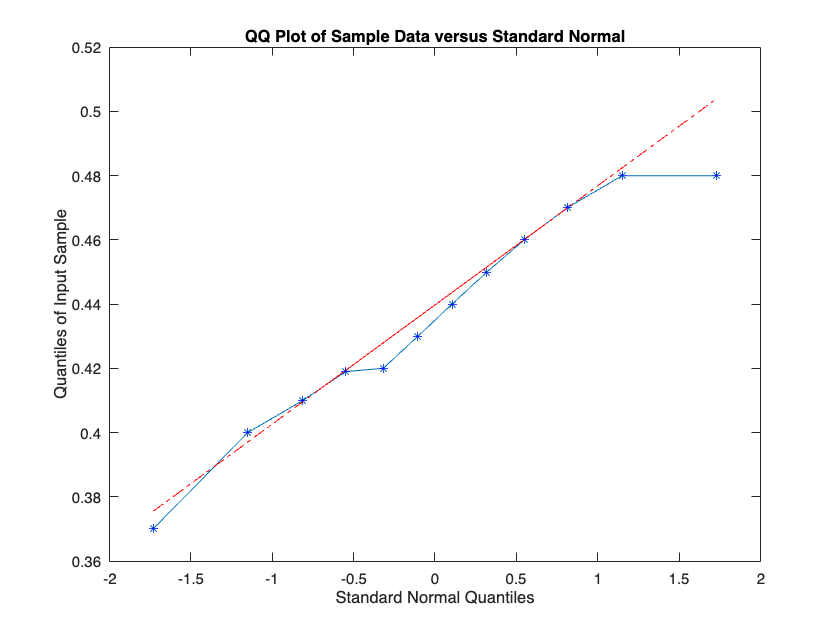

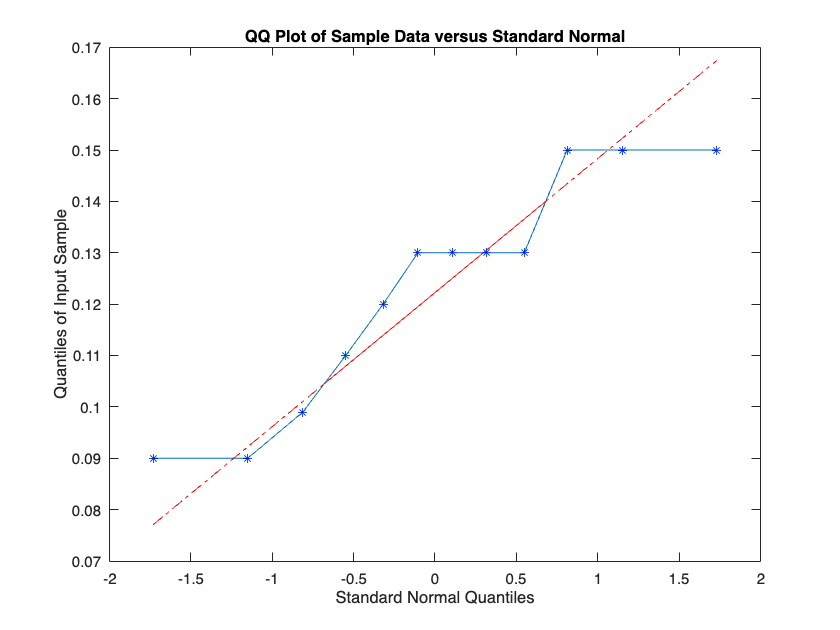

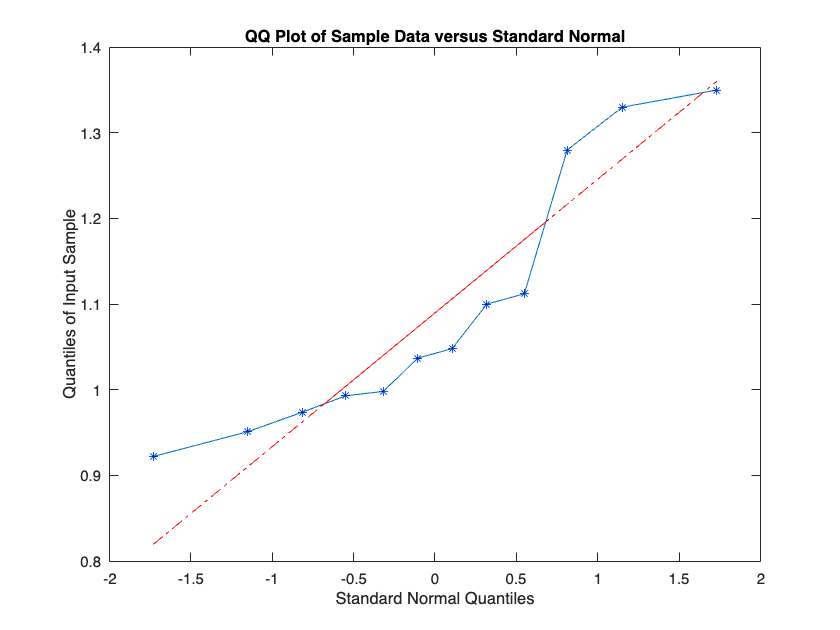


% c)
% 1) Assess whether each of the 4 dimensions is normally distributed
%GROUP A
for i=1:3
    figure;
    myqqplot(groupA(:,i));
    hold on ;
    qqplot(groupA(:,i));
    hold off;
end

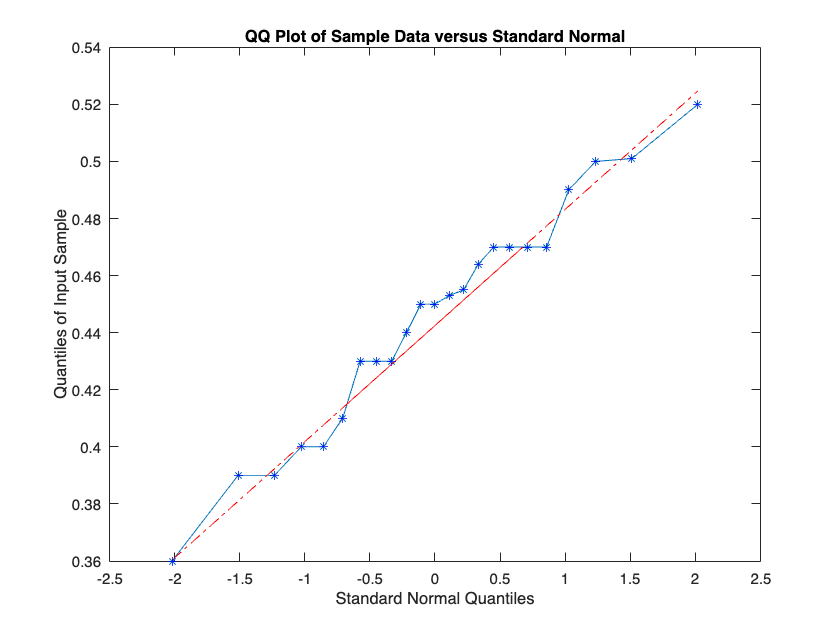

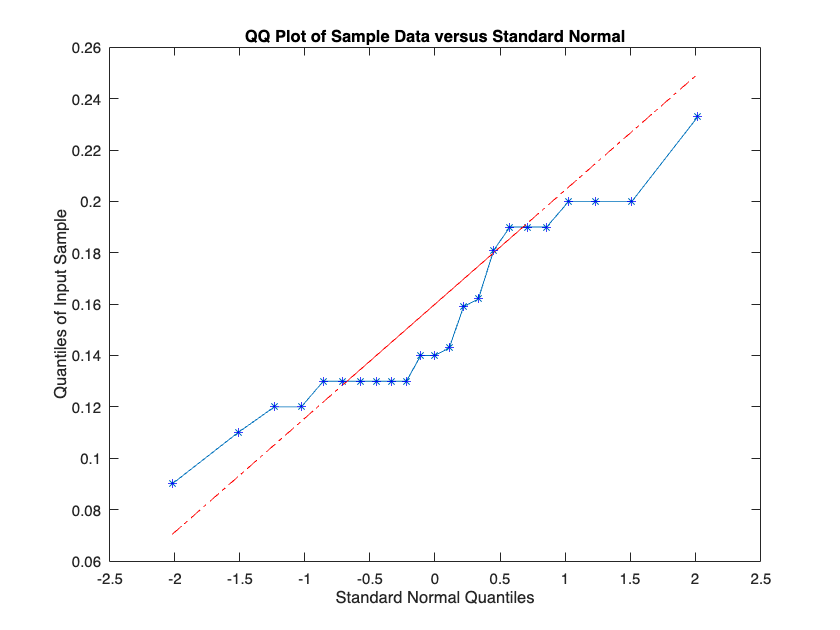

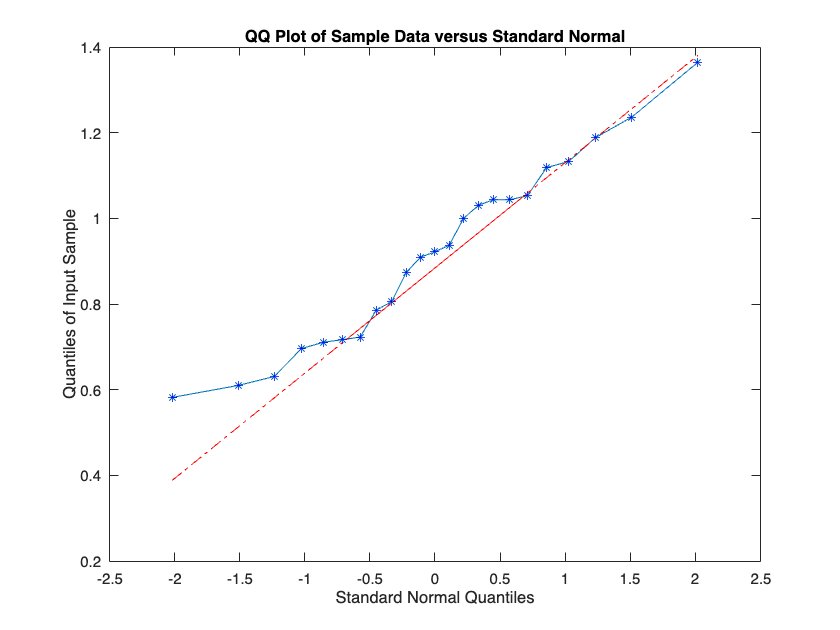

%GROUP B
for i=1:3
    figure;
    myqqplot(groupB(:,i));
    hold on ;
    qqplot(groupB(:,i));
    hold off;
end

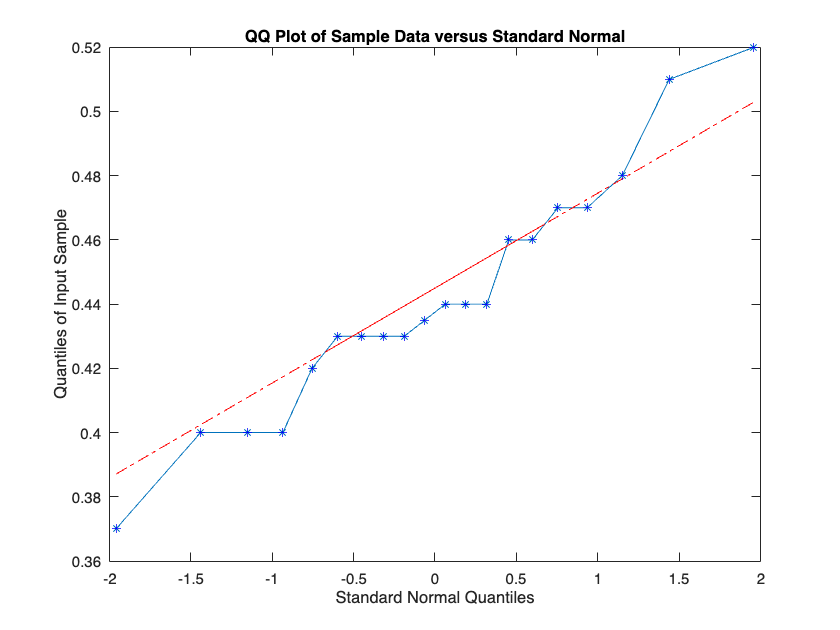

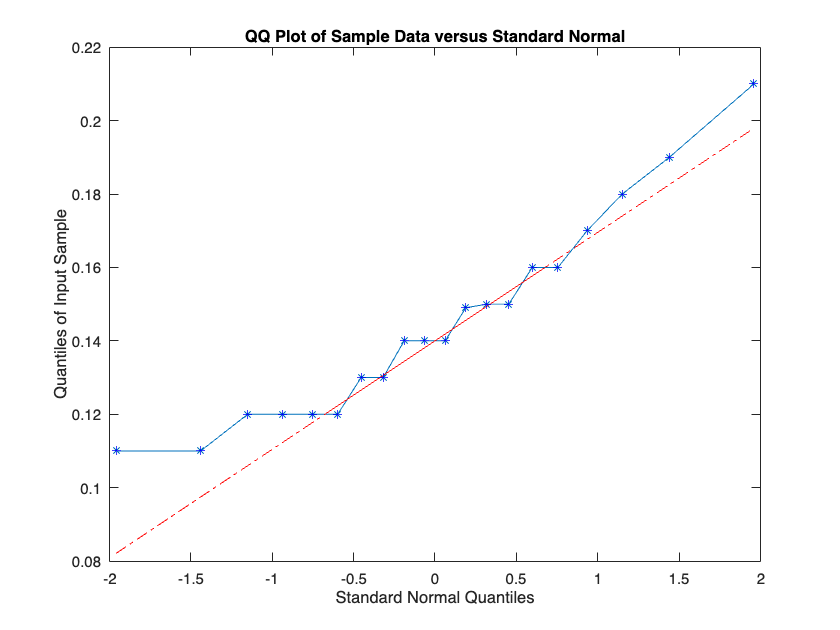

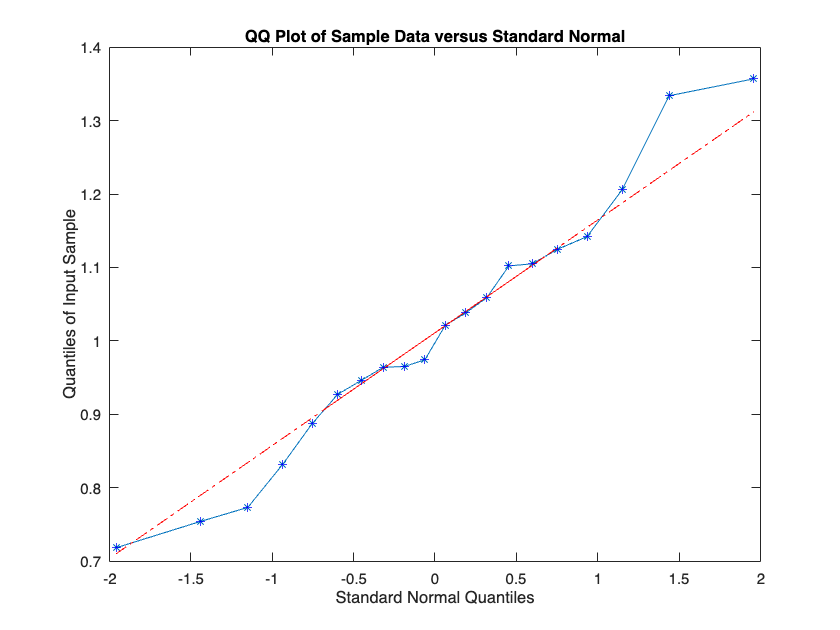

%GROUP C
for i=1:3
    figure;
    myqqplot(groupC(:,i));
    hold on ;
    qqplot(groupC(:,i));
    hold off;
end

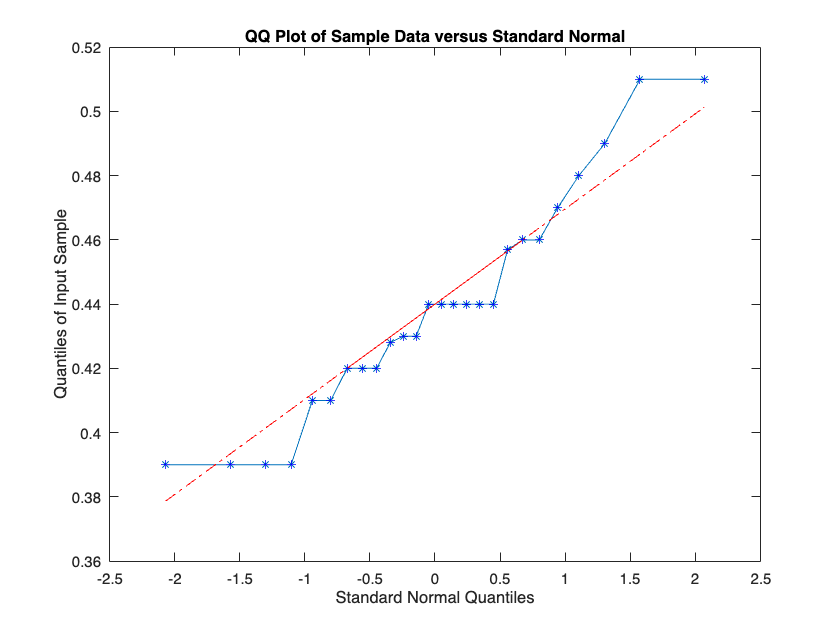

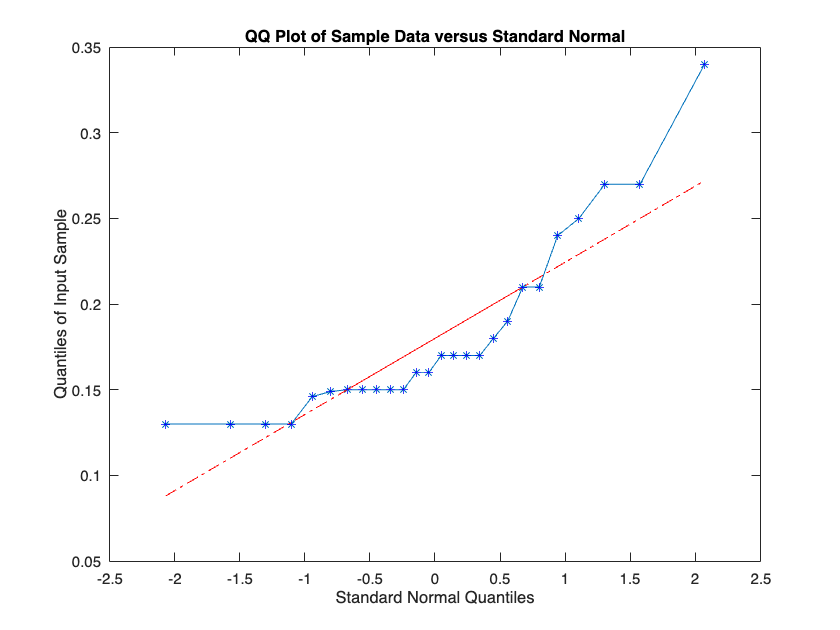

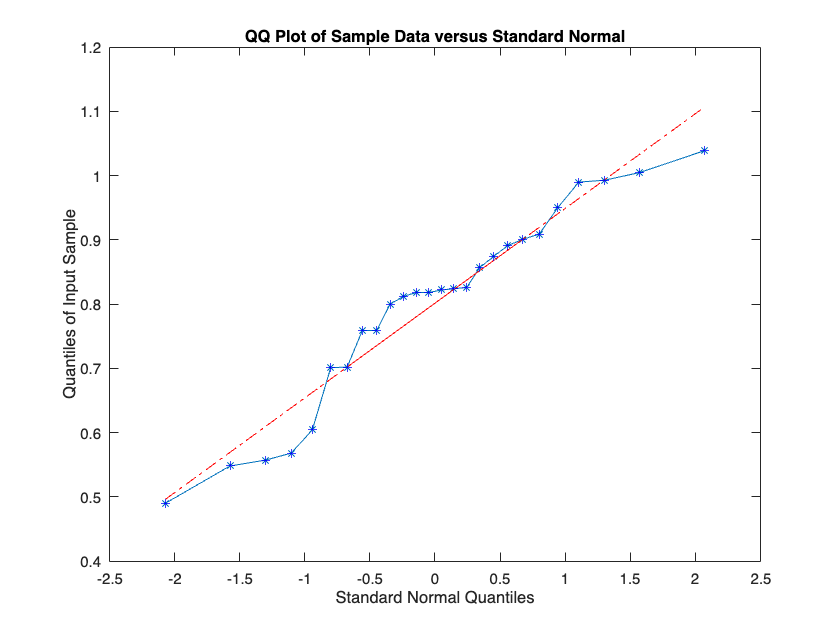

%GROUP D
for i=1:3
    figure;
    myqqplot(groupD(:,i));
    hold on ;
    qqplot(groupD(:,i));
    hold off;
end

%group A
qA = norminv(((1:length(groupA))-0.5)/length(groupA));

for i=1:3
    correlation_coefficient = corr(sort(groupA(:,i)), qA')
end

correlation_coefficient = 0.9833

correlation_coefficient = 0.9542

correlation_coefficient = 0.9371

%group B
qB = norminv(((1:length(groupB))-0.5)/length(groupB));

for i=1:3
    correlation_coefficient = corr(sort(groupB(:,i)), qB')
end

correlation_coefficient = 0.9896

correlation_coefficient = 0.9648

correlation_coefficient = 0.9872

 
%group C
qC = norminv(((1:length(groupC))-0.5)/length(groupC));
for i=1:3
    correlation_coefficient = corr(sort(groupC(:,i)), qC')

end

correlation_coefficient = 0.9805

correlation_coefficient = 0.9687

correlation_coefficient = 0.9892

 %group D
qD = norminv(((1:length(groupD))-0.5)/length(groupD));
for i=1:3

    correlation_coefficient = corr(sort(groupD(:,i)), qD')

end

correlation_coefficient = 0.9743

correlation_coefficient = 0.9100

correlation_coefficient = 0.9757


%GROUP A
%If your method requires any assumptions regarding variances or covariances, assess whether the data fulfills such assumption(s). Make sure to state your conclusion.

%with matlab function
gA = cov(groupA)

gA =     0.0012   -0.0001   -0.0002
   -0.0001    0.0005   -0.0027
   -0.0002   -0.0027    0.0223


gB = cov(groupB)

gB =     0.0016    0.0007   -0.0041
    0.0007    0.0013   -0.0071
   -0.0041   -0.0071    0.0465


gC = cov(groupC)

gC =     0.0014    0.0003   -0.0031
    0.0003    0.0007   -0.0040
   -0.0031   -0.0040    0.0308


gD = cov(groupD)

gD =     0.0012    0.0010   -0.0023
    0.0010    0.0028   -0.0069
   -0.0023   -0.0069    0.0228


%with my function
covA = myCov(groupA)

covA =     0.0011   -0.0001   -0.0002
   -0.0001    0.0004   -0.0025
   -0.0002   -0.0025    0.0204


covB = myCov(groupB)

covB =     0.0016    0.0006   -0.0040
    0.0006    0.0013   -0.0068
   -0.0040   -0.0068    0.0445


covC = myCov(groupC)

covC =     0.0013    0.0003   -0.0029
    0.0003    0.0007   -0.0038
   -0.0029   -0.0038    0.0293


covD = myCov(groupD)

covD =     0.0011    0.0010   -0.0023
    0.0010    0.0027   -0.0067
   -0.0023   -0.0067    0.0219


meanX =     0.4358
    0.1232


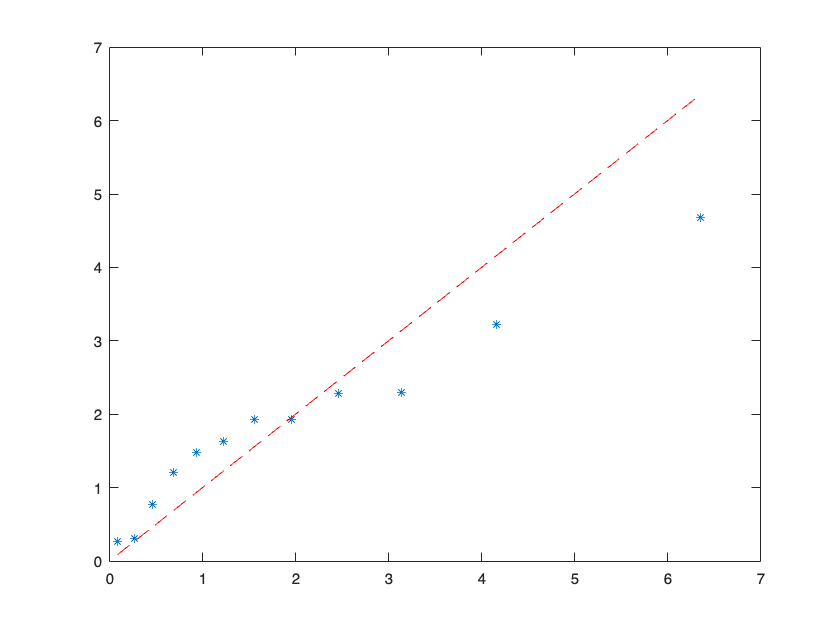

% 2) Assess whether each pair of dimensions is normally distributed -->
% chi-square

%descarded 1 group D
%group A
comb1A = [groupA(:,1), groupA(:,2)];
comb2A = [groupA(:,1), groupA(:,3)];
comb3A = [groupA(:,2), groupA(:,3)];

mychi2plot(comb1A');

meanX =     0.4358
    1.0912


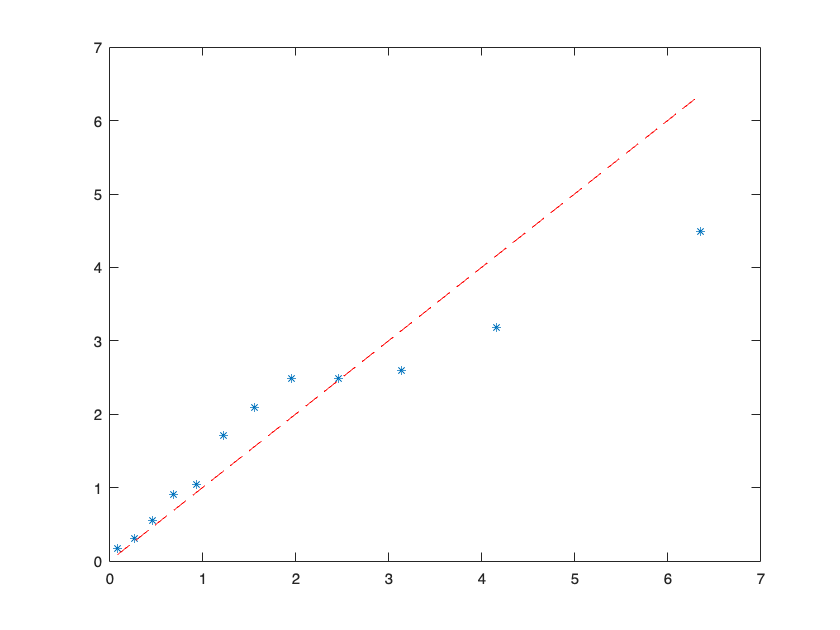

mychi2plot(comb2A');

meanX =     0.1232
    1.0912


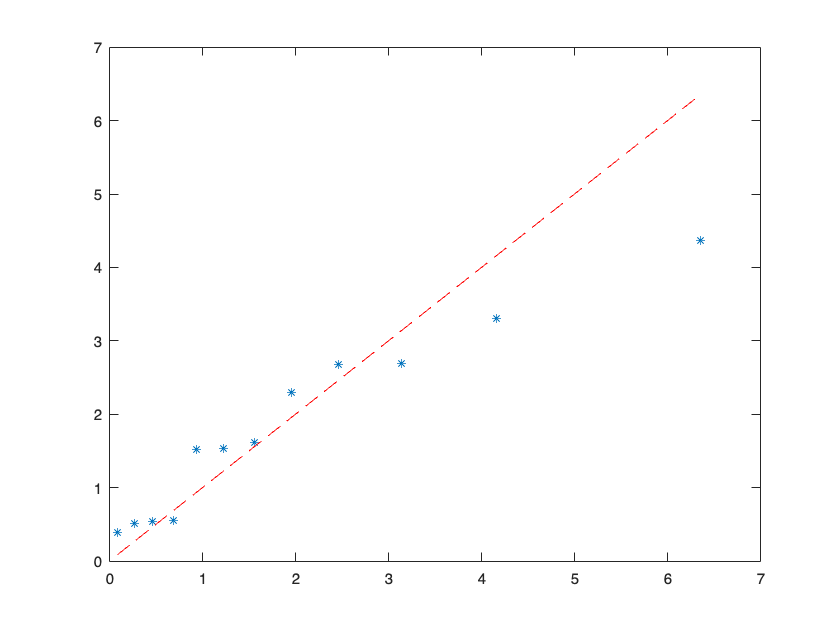

mychi2plot(comb3A');

meanX =     0.4358
    0.1232
    1.0912


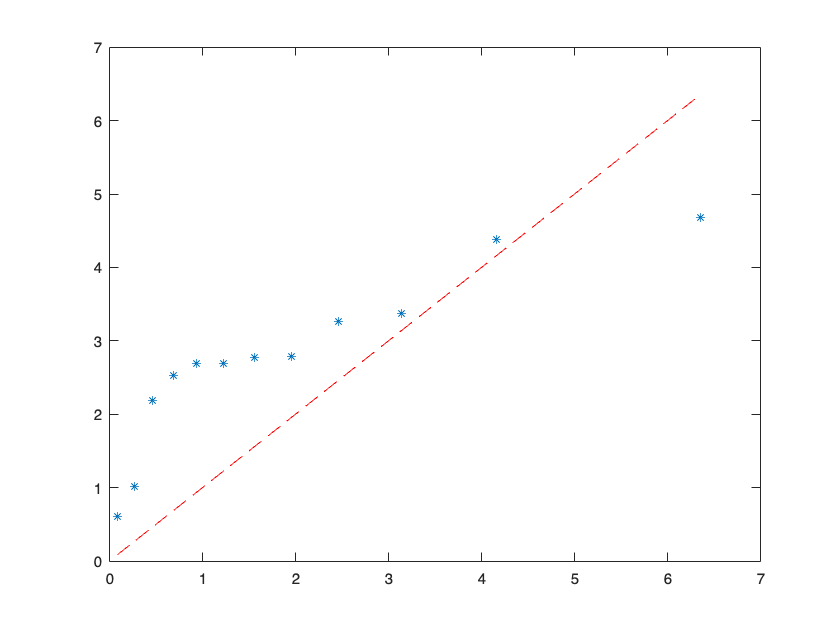

mychi2plot(groupA');

meanX =     0.4453
    0.1543


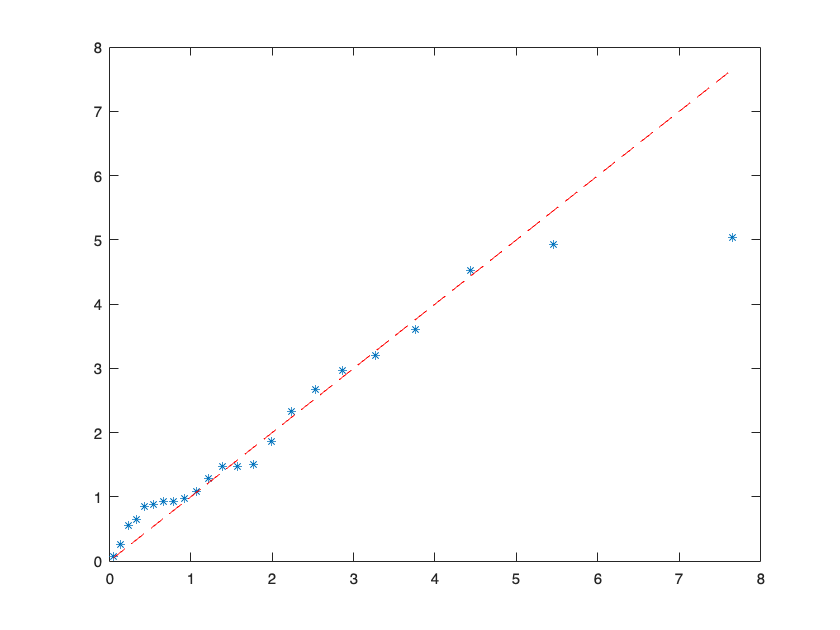


%group B
comb1B = [groupB(:,1), groupB(:,2)];
comb2B = [groupB(:,1), groupB(:,3)];
comb3B = [groupB(:,2), groupB(:,3)];

mychi2plot(comb1B');

meanX =     0.4453
    0.9183


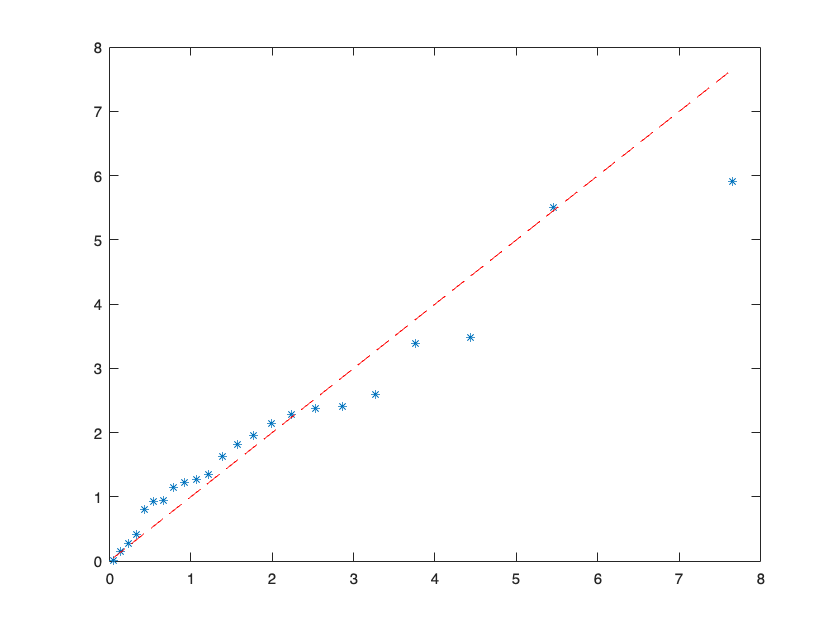

mychi2plot(comb2B');

meanX =     0.1543
    0.9183


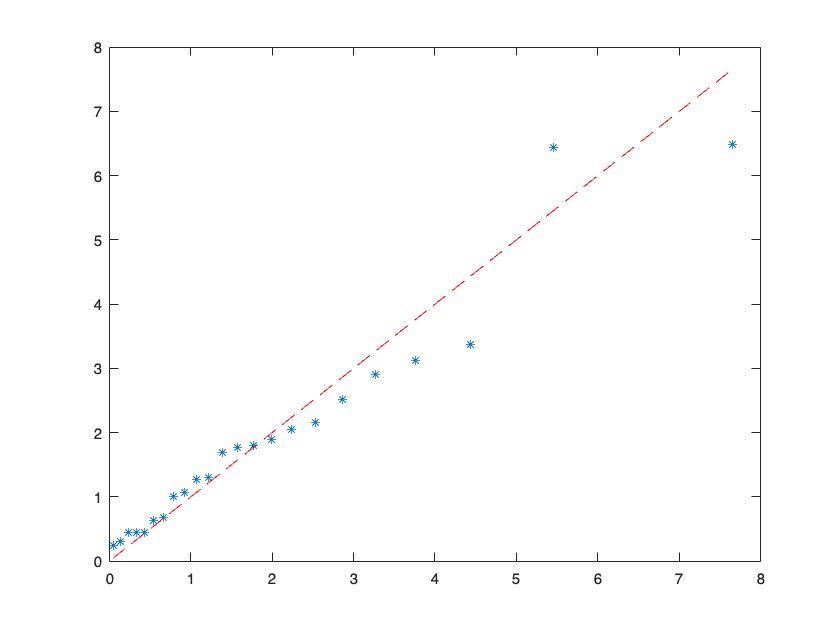

mychi2plot(comb3B');

meanX =     0.4453
    0.1543
    0.9183


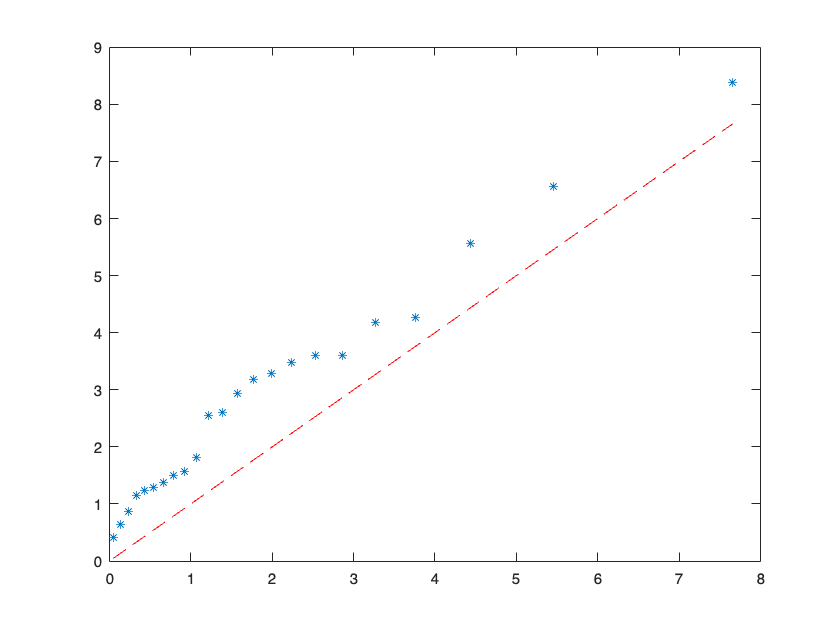

mychi2plot(groupB');

meanX =     0.4418
    0.1450


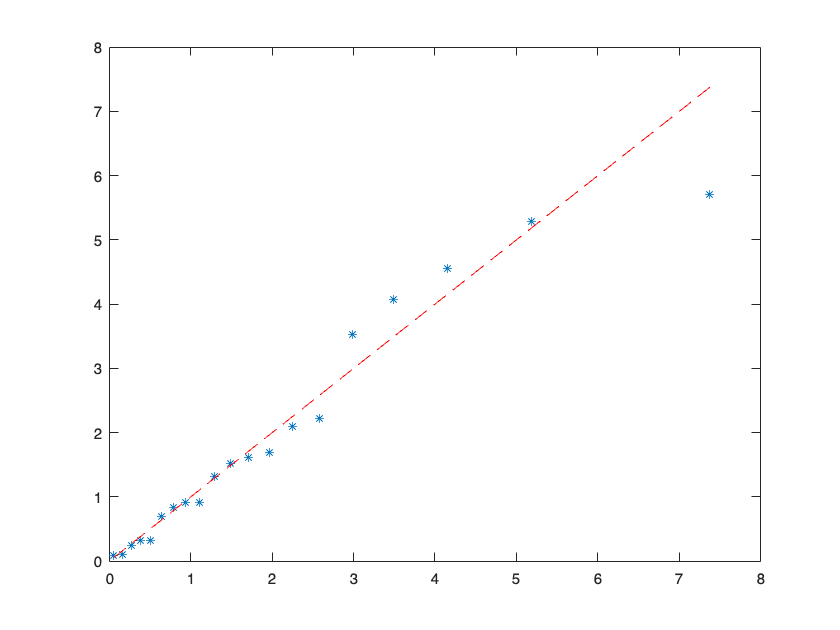

%group C
comb1C = [groupC(:,1), groupC(:,2)];
comb2C = [groupC(:,1), groupC(:,3)];
comb3C = [groupC(:,2), groupC(:,3)];

mychi2plot(comb1C');

meanX =     0.4418
    1.0115


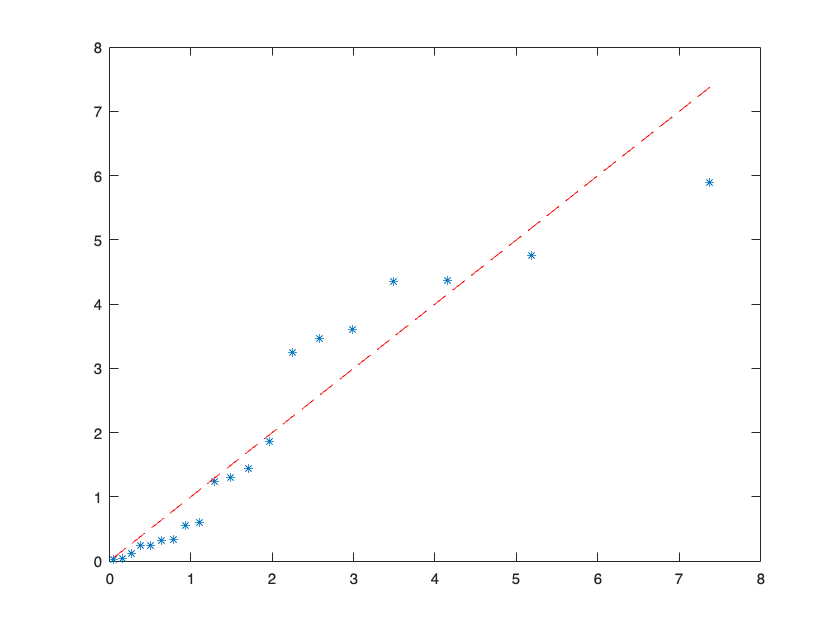

mychi2plot(comb2C');

meanX =     0.1450
    1.0115


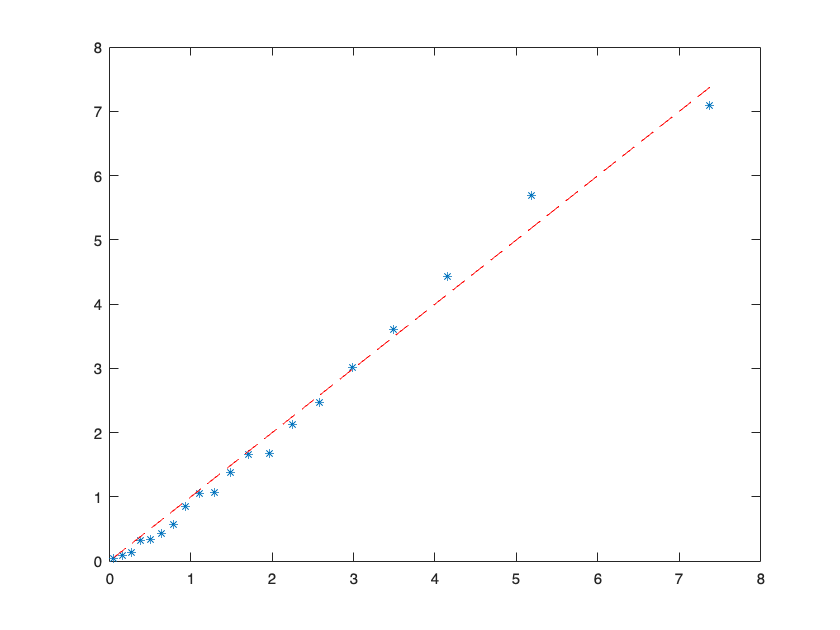

mychi2plot(comb3C');

meanX =     0.4418
    0.1450
    1.0115


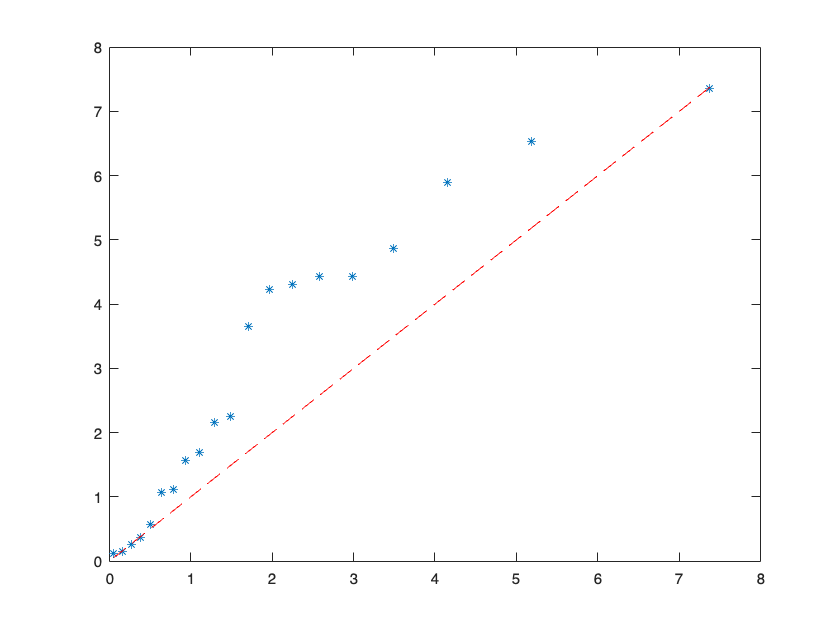

mychi2plot(groupC');

% f)Apply the method selected in (a) to answer the research question, at significance level α = 0.05. if you performed any fixing in (e), then use the fixed data. Indicate your conclusions.

n = length(datawithoutD(:,1));
g = length(datawithoutD(i,:));
N = length(groupA) + length(groupB) + length(groupC)

N = 55

p=3;

means = zeros(3, 3);

for i=1:3
    means(i, 1) = mean(groupA(:, i));
end

for i=1:3
    means(i,2) = mean(groupB(:,i));
end

for i=1:3
    means(i,3) = mean(groupC(:,i));
end


for i=1:3
    mymeanov(i) = mean(datawithoutD(:,i));
end



diffTotal = means - mymeanov';
mySSB = 12 * (diffTotal * diffTotal') + 23*(diffTotal * diffTotal') + 20*(diffTotal * diffTotal');
mySSW = zeros(3,3);

for i = 1:g
    for j = 1:12
        mygData = datawithoutD(1:j, :)';
        mygData = (mygData - means(:,i))*(mygData - means(:,i))';
        mySSW = mySSW + mygData;
    end
end

mylambda = det(mySSW)/det(mySSB + mySSW)

mylambda = 0.8203

DFSSb = g - 1;
DFSSw = N - g;
s = min(p,DFSSw);

DF1 = p*DFSSb;
DF2 = s*(DFSSw-((p-DFSSb+1)/2))-((p*DFSSb-2)/2);

% using Wilks' Lambda

F = ((1-sqrt(mylambda))/DF_1)/(sqrt(mylambda)/DF_2)

F = 0.7809


% Calculate the critical F-value 
Fcritic = finv(0.95, DF1, DF2)

Fcritic = 2.1591

%functions

function covariance_matrix = myCov(x)
    n = length(x);
    mu = mean(x);    
    centered_data = x - mu;    
    covariance_matrix = (centered_data' * centered_data) / n;
end

function myqqplot(x)
    %quantiles
    q = norminv(((1:length(x))-0.5)/length(x));
    plot(q, sort(x), '-*');
end

function mychi2plot(x)
    meanX = mean(x')'
    s = cov(x');
    dj = [];
    qc = chi2inv(((1:length(x))-0.5)/length(x),2);
    for j=1: length(x)
        dj = [dj, (x(:,j) - meanX)'*inv(s)*(x(:,j) - meanX)];
    end
    figure;
    plot(qc, sort(dj), '*');
    hold on;
    plot(qc,qc,'r--'); %slope 1
    hold off;
end

